# Treasure Hunt Game

Welcome to this MATLAB Module designed to teach you how to make a fun treasure hunting game, while learning some core Computer Science concepts along the way. We recommend that you complete our other module: Fundementals of Programming to help better understand the concepts brought up in this module. Hope you enjoy!

The game will look like this when it is finished:

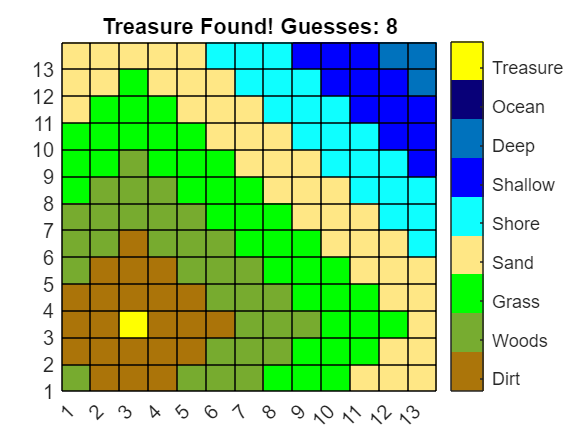

## Section 1: Creating Variables

Variables are a great way to store information to use for later. Some information for this game we want to save includes: the board size, the treasure location, and the numer of guesses made.

First let's start off by making a variable to represent the number of guesses the player has made. I recommend calling this guessNum. We want this variable to be equal to zero because at the start of the game the player will have made zero guesses. 

%Number of guesses the player made
guessNum = 0

guessNum = 0

Next let's move onto the board size. Start by naming your variables. I recommend: columns and rows or length and width. If you prefer, instead you can include only one variable if you want the board to always be a square.

Once your variables have a name, they must equal something. In this case we want them to be an integer that is between 6 and 20.

columns = 15

columns = 15

rows = 15 

rows = 15

If you want to allow the player to change the size of the board to make the game harder or easier, we can add a live control to make that easier for them. You can add a slider to change the value as you wish (Under Control in the Live editor Tab). To edit the slider configurations: Right Click -> Configure controls. Choose a min and max value for the sliders.

columns = 14

columns = 14

rows = 14

rows = 14

You can use old variables to make new ones. Try subtracting one from the columns and rows variable and equate it to a new variable. This variable will be the true boundary of our board. 

limitC = columns - 1

limitC = 13

limitR = rows - 1

limitR = 13

A matlab built in function allows you to easily excute an operation. Functions can be used to generate new variables. The randi function will generate psuedorandom integers. For the input we want to specify the min and the max which will be equal to the bounds of our board. These random values will be equal to a coordinate for our treasure chest. Here is the doc page where you can find more information on this function: [Uniformly distributed pseudorandom integers - MATLAB randi (mathworks.com)](https://www.mathworks.com/help/matlab/ref/randi.html)

treasureX = randi([1 limitC])

treasureX = 11

treasureY = randi([1 limitR])

treasureY = 12

## Working with Matricies

Matlab was originally created to help solve complex linear algebra problems, involving matricies. A matrix is an r x c array of numbers, where r is the number of rows and c is the number of columns. We already specified our row and column height early so now we can use those variables to create our matrix which will represent our entire board or treasure map. 

In order to create our first matrix we want to use another function. One such function we can use is the zeros function. This function creates a matrix that is made up of zeros that is the size of the rows and columns we specify in the input. More information on the zeros function can be found here: [Create array of all zeros - MATLAB zeros (mathworks.com)](https://www.mathworks.com/help/matlab/ref/zeros.html#:~:text=X%20%3D%20zeros(%20sz%20)%20returns,2%2Dby%2D3%20matrix.&text=X%20%3D%20zeros(___%2C%20typename%20)%20returns%20an%20array%20of,%2C%208%2Dbit%20integer%200%20.)

%Creates the blank map
map = zeros(rows, columns)

map =      0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Great! Now we have a matrix that is the correct size we want that is filled with zeros. Now let's take the zeros in the matrix and transform them into NaNs.

NaN stands for Not a Number. The reason we want all the values to be equal to NaN is for the initial board state. Matlab interpts NaN values as white and this is exactly what we want for our empty map. 

We need MATLAB to go through the entire matrix and change any value that is a zero into NaN. There is a neat little trick we can use to do this. Use our matrix of zeros and put soem parentheses next to it. Inside these paretheses we want: (var == 0).

If we have two equal signs, this means that MATLAB is asking a question. MATLAB is asking if the two values are equal to each other. If that statement is true then MATLAB will equate the value to NaN. This statement should be true for our entire matrix. 

map(map == 0) = NaN

map =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


Now we want to use another built-in MATLAB function. This one is called meshgrid. The reasone we are use meshgrid is to map each of the points in our matrix to an x,y coordinate. 

[2-D and 3-D grids - MATLAB meshgrid (mathworks.com)](https://www.mathworks.com/help/matlab/ref/meshgrid.html)

%Creates the colored in Map
[x2,y2] = meshgrid(1:columns,1:rows)

x2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14


y2 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     6     6     6     6     6     6     6     6     6     6     6     6     6     6
     7     7     7     7     7     7     7     7     7     7     7     7     7     7
     8     8     8     8     8     8     8     8     8     8     8     8     8     8
     9     9     9     9     9     9     9     9     9     9     9     9     9     9
    10    10    10    10    10    10    10    10    10    10    10    10    10    10


Now that we have our board and our treasure location we want to calculate the distance from each coordinate point to our treasure. We can use the Taxicab Metric to calculate the distance between two coordinates points. This external link provides some great insight on how to calculate the Taxicab Metric: [Taxicab Metric -- from Wolfram MathWorld](https://mathworld.wolfram.com/TaxicabMetric.html)

The Taxicab Metric requires us to find the absolute value. There is a built-in MATLAB function that can do this for us called abs. More information on the abs function can be found here: 

[Absolute value and complex magnitude - MATLAB abs (mathworks.com)](https://www.mathworks.com/help/matlab/ref/abs.html)

taxiMatrix = abs(treasureY - y2(:))+ abs(treasureX - x2(:))

taxiMatrix =     21
    20
    19
    18
    17
    16
    15
    14
    13
    12


You may have noticed that the output of our Taxicab formula produced a vector. We need to convert our vector back into a Matrix. In order to do this let's use the reshape function. It takes three inputs, our vector and the rew and column size. More information on the reshape function can be found here: [Reshape array - MATLAB reshape (mathworks.com)](https://www.mathworks.com/help/matlab/ref/reshape.html)

finalMap = reshape(taxiMatrix,rows,columns)

finalMap =     21    20    19    18    17    16    15    14    13    12    11    12    13    14
    20    19    18    17    16    15    14    13    12    11    10    11    12    13
    19    18    17    16    15    14    13    12    11    10     9    10    11    12
    18    17    16    15    14    13    12    11    10     9     8     9    10    11
    17    16    15    14    13    12    11    10     9     8     7     8     9    10
    16    15    14    13    12    11    10     9     8     7     6     7     8     9
    15    14    13    12    11    10     9     8     7     6     5     6     7     8
    14    13    12    11    10     9     8     7     6     5     4     5     6     7
    13    12    11    10     9     8     7     6     5     4     3     4     5     6
    12    11    10     9     8     7     6     5     4     3     2     3     4     5


Now that we have our Matrix filled in, we want to make sure the treasure shows up correctly when we plot it later. You can index into your matrix and change specific values. We want to index to our treasure's location and change it to a really high value. I recommend 500. 

%Treasure is very high values to it shows up correctly
finalMap(treasureY,treasureX) = 500

finalMap =     21    20    19    18    17    16    15    14    13    12    11    12    13    14
    20    19    18    17    16    15    14    13    12    11    10    11    12    13
    19    18    17    16    15    14    13    12    11    10     9    10    11    12
    18    17    16    15    14    13    12    11    10     9     8     9    10    11
    17    16    15    14    13    12    11    10     9     8     7     8     9    10
    16    15    14    13    12    11    10     9     8     7     6     7     8     9
    15    14    13    12    11    10     9     8     7     6     5     6     7     8
    14    13    12    11    10     9     8     7     6     5     4     5     6     7
    13    12    11    10     9     8     7     6     5     4     3     4     5     6
    12    11    10     9     8     7     6     5     4     3     2     3     4     5


The last thing we want to do before setting up our plot is set the colors for our colormap. A colormap is a matrix full of values that will represent how far away you are from the treasure. I chose eight different colors for my colormap. The last colors should represent the treasure.

One of the ways that colors are represent in MATLAB are by their RGB value. RGB stands for Red Green Blue. All possible colors can be created depending on how much Red Green and Blue you put into it.

An option to find the RGB values for the colors you want to use for your color map is to use a built-in MATLAB app called uisetcolor. You can type this into the MATLAB Command Window and the app will pop up and let you pick colors. It will then output the RGB value for you to use. More information on uisetcolor can be found here:

[Open color picker - MATLAB uisetcolor (mathworks.com)](https://www.mathworks.com/help/matlab/ref/uisetcolor.html)

%The colormap for the board with different colors to simulate an island
cmap = [0.6706 0.4588 0.0392; 0.4667 0.6745 0.1882; 0 1 0;1 0.9059 0.5216;0.0588 1 1; 0 0 1; 0 0.4471 0.7412;0.0314 0 0.4706; 1 1 0]

cmap =     0.6706    0.4588    0.0392
    0.4667    0.6745    0.1882
         0    1.0000         0
    1.0000    0.9059    0.5216
    0.0588    1.0000    1.0000
         0         0    1.0000
         0    0.4471    0.7412
    0.0314         0    0.4706
    1.0000    1.0000         0


## Creating Plots and Modifying Them

%Board Setup
p = pcolor(map)

p =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14]
           YData: [14×1 double]
           ZData: [14×14 double]
           CData: [14×14 double]

  Show all properties


hold on
xticks(1:1:limitC)
yticks(1:1:limitR)

colormap(cmap)
clim([0 rows*2])

c = colorbar

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 28]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


c.Ticks = 1:rows*2/9:rows*2;
c.TickLabels = {'Dirt','Woods','Grass','Sand','Shore','Shallow','Deep','Ocean', 'Treasure'};

title("Find the Treasure!")

## If Statements and User Input

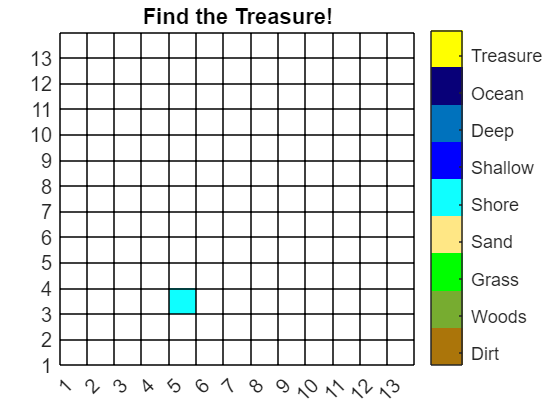

You are 15 away from the treasure.
Guess: 1
Guess again!


%Play Game
 

if(guessNum ~= 0)
    guessX = 5;
    guessY = 3;

    %Run function to check guesses
    playGame(treasureX,treasureY,map,finalMap,guessX,guessY,guessNum)
    guessNum = guessNum + 1;
else
    %Increments the Guess Numbers to start the game
    guessNum = guessNum + 1;
end

## Creating and Using Functions

function playGame(tX,tY,m,fm,gX,gY,gN)
    
    %If the guess is equal to the treasure location
    if(gX == tX)&&(gY == tY)
        %Fill in the whole grid
        pcolor(fm);
        %Display the new title
        finish = "Treasure Found! Guesses: " + gN;
        title(finish);
    %If the guess is not equal to the treasure
    else
        %Fill in the color of the location the guessed
        m(gY,gX) = fm(gY,gX);
        pcolor(m);
        
        %Display hint and guess number
        help = "You are " + string(fm(gY,gX)) + " away from the treasure.";
        guess = "Guess: " + gN;
        disp(help);
        disp(guess);
        disp("Guess again!");
        
    end
end